## Rotor

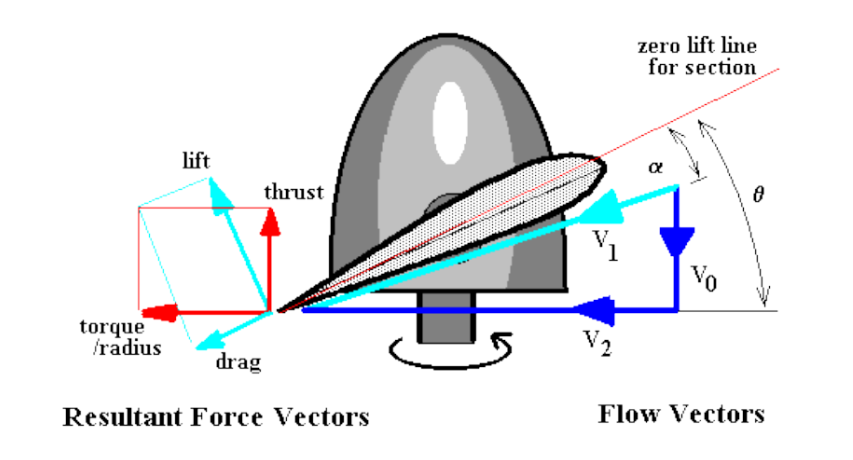

theta = 5;
alpha = 5;
rho = 1.225;

R = 0.4;
    c=0.15;
V1 = 0;
V2 = 0;

B = 2;
segments = 250;
r_seg = 0:R/segments:R;

torque_profile = zeros(1,length(r_seg));
thrust_profile = zeros(1,length(r_seg));
V0 = zeros(1,length(r_seg));
F= 0.05;
iterations = 3;
torque_P = zeros (iterations,length(r_seg));  
thrust_P = zeros (iterations,length(r_seg));
vortex_strength = zeros (iterations,length(r_seg));
vortex_tangentail_velcoity = zeros (1,length(r_seg));
total_torque =0

total_torque = 0

Torque_thrust = F*R*2

Torque_thrust = 0.0400

torque_speed_curve = zeros (1,800/10);
thrust_speed_curve = zeros (1,800/10);

%omega=570
count =1

count = 1

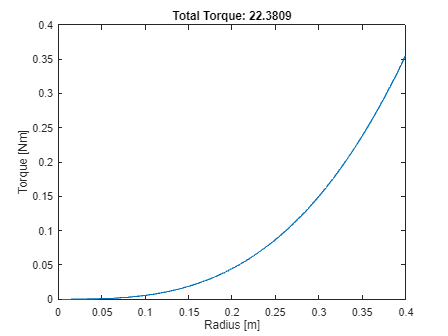

for x =10:10:800
% omega = Omega_Estimate(Cl(alpha),rho,Torque_thrust,c,theta-alpha,Cd(alpha), B,V0(end),.69349*R)
    omega = x;
    thrust_profile = zeros(1,length(r_seg));
    V02 = 0;
    for j = 1:iterations
    % alpha = theta - atand(sum(V0(2:length(r_seg)))./length(r_seg)/(3./4.*R.*omega));
    alpha = theta - atand(V02./length(r_seg)/(3./4.*R.*omega));

    for i = 1:length(r_seg)
        thrust_profile(i) = Thrust(Cl(alpha),rho,omega,r_seg(i),c,theta-alpha,Cd(alpha), B,V0(i),R/segments) * 0.98;
        torque_profile(i) = Torque(Cl(alpha),rho,omega,r_seg(i),c,theta-alpha,Cd(alpha), B,V0(i),R/segments);
        %V0(i) = sqrt(torque_profile(i)/(pi .* (r_seg(i)+R/segments).^2 .* rho ))-vortex_tangentail_velcoity(i);
        % V0(i) = sqrt(thrust_profile(i)/(pi .* (r_seg(i)+R/segments).^2 .* rho ));
        thrust_P(j,i)=thrust_profile(i);
        torque_P(j,i)=torque_profile(i);
        %vortex_strength(j,i) = (thrust_profile(i)./(cosd(theta-alpha)));
        %vortex_tangentail_velcoity(i) =  vortex_strength(i)/(2*pi*r_seg(i));
    
    end
    dr(1,0.12);
    %thrust_profile(50);
    %omega = 
    end

    total_thrust = sum(thrust_profile(4:end));
    total_torque = sum(torque_profile(4:end));
    V02 = sqrt(total_thrust/(pi * R.^2 .* rho));
    torque_speed_curve((x/10)) = total_torque;
    thrust_speed_curve((x/10)) = total_thrust;

end

% V0
plot(r_seg(4:end),torque_P(1,4:end))
xlabel('Radius [m]');
ylabel('Torque [Nm]');
title(['Total Torque: ', num2str(total_torque)]);

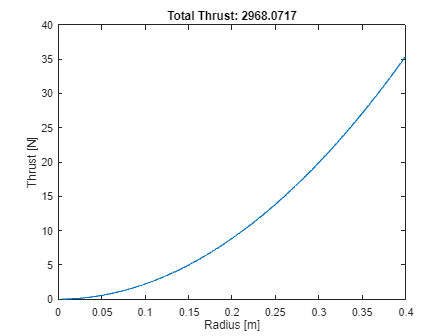


plot(r_seg(4:end),thrust_P(end,4:end)) 
xlabel('Radius [m]');
ylabel('Thrust [N]');
title(['Total Thrust: ', num2str(total_thrust)]);

alpha

alpha = 5

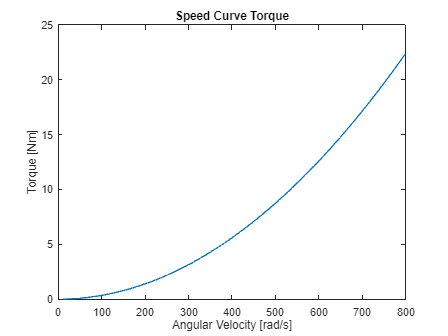

plot((10:10:800),torque_speed_curve)
title("Speed Curve Torque")
xlabel('Angular Velocity [rad/s]');
ylabel('Torque [Nm]');

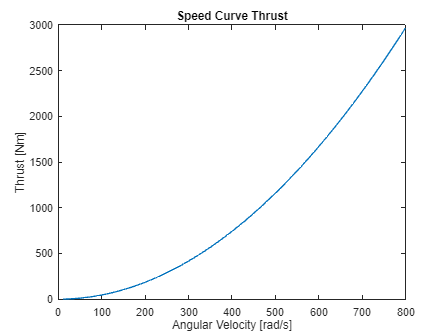

% pp = spline((0:10:800),torque_speed_curve)
% pp.coefs
plot((10:10:800),thrust_speed_curve)
title("Speed Curve Thrust")
xlabel('Angular Velocity [rad/s]');
ylabel('Thrust [Nm]');

%plot(r_seg,V0-vortex_tangentail_velcoity)

## Angle of attack 

interval =0.5

interval = 0.5000

AOA_Vs_Thrust = zeros(1, 14/interval);
omega_AOA_profile = zeros(1, 8)

omega_AOA_profile =      0     0     0     0     0     0     0     0


% for omega = 10:10:100
omega = 32.84

omega = 32.8400

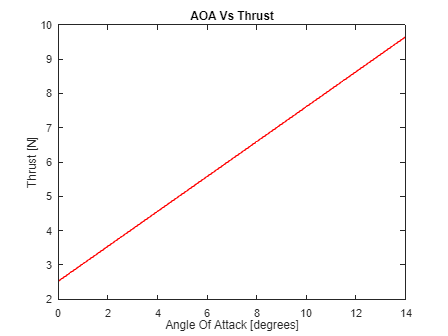


for AOA = 0:interval:14
    theta = AOA;
    thrust_profile = zeros(1,length(r_seg));
    V02 = 0;
    for j = 1:iterations
    alpha = theta - atand(V02./length(r_seg)/(3./4.*R.*omega));

    for i = 1:length(r_seg)
        thrust_profile(i) = Thrust(Cl(alpha),rho,omega,r_seg(i),c,theta-alpha,Cd(alpha), B,V0(i),R/segments);
        torque_profile(i) = Torque(Cl(alpha),rho,omega,r_seg(i),c,theta-alpha,Cd(alpha), B,V0(i),R/segments);
        thrust_P(j,i)=thrust_profile(i);
        torque_P(j,i)=torque_profile(i);
    end
    total_thrust = sum(thrust_profile(4:end));
    total_torque = sum(torque_profile(4:end));
    V02 = sqrt(total_thrust/(pi * R.^2 .* rho));
    AOA_Vs_Thrust(AOA/interval + 1)=total_thrust;
    end
end

AOA_Vs_Thrust(end)/14;
% % omega_AOA_profile(omega/10) = (AOA_Vs_Thrust(end))/14;
% 
% end
plot(0:interval:14,AOA_Vs_Thrust,'r') 
xlabel('Angle Of Attack [degrees]');
ylabel('Thrust [N]');
title('AOA Vs Thrust');


% plot( 10:10:100, omega_AOA_profile)
% xlabel('Angular velocity [rad/s]');
% ylabel('AOA gradient [degrees]');
% title('AOA gradient Vs angular velocity');

## Propeller

% Prop_radius = 2*0.0254 %From inchs to m
% pitch = 0.0254*1.9
Prop_radius = 0.072/2   %(EFLUP72653BR )

Prop_radius = 0.0360

pitch = 0.065 ;         %(EFLUP72653BR)
nr_of_blades = 4;
% pitch = 0.2
pitch_angle = atand(pitch/(2*Prop_radius*pi))

pitch_angle = 16.0327

speed = 800

speed = 800

prop_thrust_profile= zeros(1,speed/10);
prop_torque_profile= zeros(1,speed/10);
prop_Thrust_p1_coeffcient = zeros(1,speed/10);
prop_Thrust_p2_coefficient =  zeros(1,speed/10);
prop_Thrust_p3_coeffcient =  zeros(1,speed/10);
all_thrust_profiles = zeros(speed/10,speed/10);
all_torque_profiles = zeros(speed/10,speed/10);

start = 10;
xx = (start:10:speed).*2.*pi

xx = 1.0e+03 *

    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221    1.8850    1.9478    2.0106    2.0735    2.1363    2.1991    2.2619    2.3248    2.3876    2.4504    2.5133    2.5761    2.6389    2.7018    2.7646    2.8274    2.8903    2.9531    3.0159    3.0788    3.1416


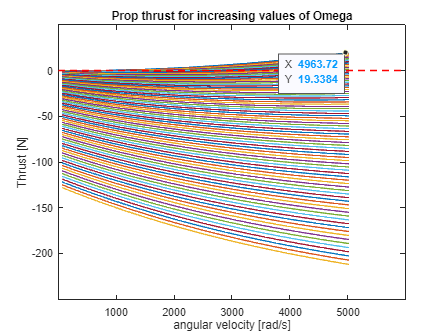



X = [start:10:speed]'.*60;

for Omega_Speed = start:10:speed
for Prop_speeds= start:10:speed
    V0_prop = Omega_Speed.*R;
    Omega_prop = Prop_speeds.*60*pi/30;
    chord_of_prop = 0.01;

    phi_prop = atand(V0_prop/(3./4.*Prop_radius.*Omega_prop));
    
    alpha_prop = pitch_angle - phi_prop;

    thrust_from_prop = Thrust(Cl(alpha_prop),rho,Omega_prop,2/3*Prop_radius,chord_of_prop,phi_prop,Cd(alpha_prop), nr_of_blades,V0_prop,2/3*Prop_radius);
    torque_of_prop = Torque(Cl(alpha_prop),rho,Omega_prop,2/3*Prop_radius,chord_of_prop,phi_prop,Cd(alpha_prop), nr_of_blades,V0_prop,2/3*Prop_radius);
    prop_thrust_profile(Prop_speeds/10) = thrust_from_prop;
    prop_torque_profile(Prop_speeds/10) = torque_of_prop;
    all_thrust_profiles(Omega_Speed/10,Prop_speeds/10)= thrust_from_prop;
    all_torque_profiles(Omega_Speed/10,Prop_speeds/10)= torque_of_prop;

    
end
plot((start:10:speed).*60.*pi/30,prop_thrust_profile)
xlabel('angular velocity [rad/s]');
ylabel('Thrust [N]');
title('Prop thrust for increasing values of Omega');
yline(0, '--r', 'LineWidth', 1.5);

hold on


FO = fit(xx',prop_thrust_profile', 'poly2');
prop_Thrust_p1_coeffcient(Omega_Speed/10) = FO.p1;
prop_Thrust_p2_coefficient(Omega_Speed/10) = FO.p2;
prop_Thrust_p3_coeffcient(Omega_Speed/10) = FO.p3;
end
hold off


prop_Thrust_p1_coeffcient

prop_Thrust_p1_coeffcient = 1.0e-05 *

    0.0853    0.0847    0.0835    0.0820    0.0803    0.0785    0.0768    0.0752    0.0738    0.0726    0.0717    0.0711    0.0707    0.0706    0.0707    0.0711    0.0716    0.0724    0.0733    0.0744    0.0756    0.0769    0.0784    0.0799    0.0814    0.0831    0.0847    0.0864    0.0882    0.0899    0.0917    0.0934    0.0952    0.0969    0.0986    0.1003    0.1020    0.1037    0.1053    0.1070    0.1085    0.1101    0.1117    0.1132    0.1147    0.1161    0.1175    0.1189    0.1203    0.1216


prop_thrust_profile

prop_thrust_profile =  -127.9910 -129.5793 -131.1509 -132.7059 -134.2445 -135.7668 -137.2729 -138.7630 -140.2372 -141.6956 -143.1384 -144.5656 -145.9775 -147.3742 -148.7558 -150.1224 -151.4741 -152.8112 -154.1336 -155.4416 -156.7353 -158.0148 -159.2803 -160.5318 -161.7695 -162.9935 -164.2039 -165.4010 -166.5847 -167.7552 -168.9127 -170.0572 -171.1890 -172.3080 -173.4144 -174.5084 -175.5901 -176.6595 -177.7169 -178.7622 -179.7957 -180.8174 -181.8275 -182.8261 -183.8132 -184.7890 -185.7537 -186.7072 -187.6498 -188.5815



Y=FO(xx);
plot(xx,Y)
xlabel('Angular veloctiy [rpm]');
ylabel('Thrust [N]');
title('Fittied vs actual graph');
hold on
plot((start:10:speed)*60.*pi/30,prop_thrust_profile)
hold off

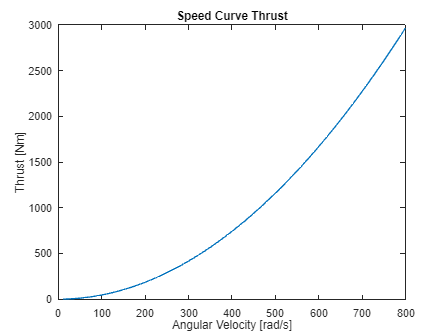

plot(start:10:speed,prop_Thrust_p3_coeffcient)
xlabel('Omega');
ylabel('Coeffcient');
title('P3 (in P1(Omega^2) + P2(Omega) + P3) Vs Omega');

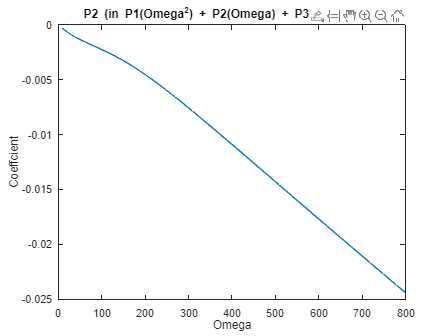


plot(start:10:speed,prop_Thrust_p2_coefficient)
xlabel('Omega');
ylabel('Coeffcient');
title('P2 (in P1(Omega^2) + P2(Omega) + P3) Vs Omega');


plot(start:10:speed,prop_Thrust_p1_coeffcient)
xlabel('Omega');
ylabel('Coeffcient');
title('P1 (in P1(Omega^2) + P2(Omega) + P3) Vs Omega');

hold on

FC2 = fit((start:10:speed)',prop_Thrust_p1_coeffcient','poly5')

FC2 =      Linear model Poly5:
     FC2(x) = p1*x^5 + p2*x^4 + p3*x^3 + p4*x^2 + p5*x + p6
     Coefficients (with 95% confidence bounds):
       p1 =  -4.171e-21  (-8.521e-21, 1.796e-22)
       p2 =   2.063e-17  (1.177e-17, 2.948e-17)
       p3 =  -3.153e-14  (-3.805e-14, -2.501e-14)
       p4 =    1.97e-11  (1.76e-11, 2.18e-11)
       p5 =  -3.693e-09  (-3.971e-09, -3.414e-09)
       p6 =   9.236e-07  (9.122e-07, 9.351e-07)

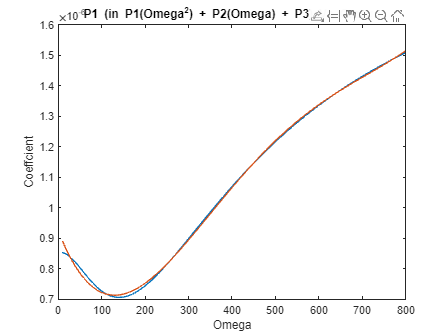

YY = FC2((start:10:speed)');
plot((start:10:speed)',YY)
hold off

% V0_prop = 200.*R;
% thrust_req = 0.5
% Omega_prop = 3.5e3
% phi_prop = atand(V0_prop/(3./4.*R.*Omega_prop))
%  V0_prop^2   
%     alpha_prop = pitch_angle -phi_prop
% 
% % Omega_prop=Omega_Thrust_Estimate(Cl(alpha_prop), rho, thrust_req,chord_of_prop, phi_prop, Cd(alpha_prop), nr_of_blades, V0_prop, 2/3*Prop_radius)
% 
% 
% 
% % prop_thrust_profile(190/5+1)
% prop_speed = zeros(1,50);
% 
% Omega_prop = 3000
% phi_prop = atand(V0_prop/(3./4.*R.*Omega_prop))
% alpha_prop = pitch_angle - phi_prop;
% req_torque = 0.50;
% 
% omega_finder = @(x) Thrust(Cl(alpha_prop),rho,x,2/3*Prop_radius,chord_of_prop,phi_prop,Cd(alpha_prop), nr_of_blades,V0_prop,2/3*Prop_radius) - req_torque
% Omega_prop = fzero(omega_finder,1700)
% Thrust(Cl(alpha_prop),rho,Omega_prop,2/3*Prop_radius,chord_of_prop,phi_prop,Cd(alpha_prop), nr_of_blades,V0_prop,2/3*Prop_radius)
% 
% (Cl(alpha_prop) * cosd(phi_prop) - Cd(alpha_prop) * sind(phi_prop)) 
% 
% 
% for i = 1:50
% phi_prop = atand(V0_prop/(3./4.*R.*Omega_prop));
% alpha_prop = pitch_angle - phi_prop;
% test = @(x) Omega_Thrust_Estimate(Cl(alpha_prop), rho, x,chord_of_prop, phi_prop, Cd(alpha_prop), nr_of_blades, V0_prop, 2/3*Prop_radius,Omega_prop);
% 
% 
% Omega_prop = test(req_torque);
% prop_speed(i) = Omega_prop;
% Thrust(Cl(alpha_prop),rho,Omega_prop,2/3*Prop_radius,chord_of_prop,phi_prop,Cd(alpha_prop), nr_of_blades,V0_prop,2/3*Prop_radius);
% thrust_from_prop = Thrust(Cl(alpha_prop),rho,Omega_prop,2/3*Prop_radius,chord_of_prop,phi_prop,Cd(alpha_prop), nr_of_blades,V0_prop,2/3*Prop_radius);
% end
% fplot(omega_finder,[0,48000])
% % help fplot
% plot(1:50, prop_speed)
% 
% Total_Torque = 2*thrust_from_prop * 2*R
% 
% plot(0:5:speed,prop_thrust_profile)
% title("Prop Thrust Curve")
% yline(0, 'r--', 'LineWidth', 1);
% 
% plot(0:5:speed,prop_torque_profile)
% title("Prop Torque Curve")
% yline(0, 'r--', 'LineWidth', 1);
% 

## Curve Fitting

X = [(10:10:800)]';
Thrust_function = fit(X,thrust_speed_curve', 'power1')
Torque_function = fit(X,torque_speed_curve','power1')
prop_A_coef = fit((start:10:speed)',prop_Thrust_p1_coeffcient','poly6');
prop_B_coef = fit((start:10:speed)',prop_Thrust_p2_coefficient','poly6');
prop_C_coef = fit((start:10:speed)',prop_Thrust_p3_coeffcient','poly6');
FO = fit(X.*60,prop_thrust_profile', 'poly2');


## Speed for thrust calculator

Thrust_req = 25

Thrust_req = 25



omega_for_thrust = @(x) (x./Thrust_function.a).^(1/Thrust_function.b);
Torque_for_thrust = @(x) Torque_function.a.*omega_for_thrust(x).^Torque_function.b;
Thrust_requried = Torque_for_thrust(Thrust_req)/(2*R);
omega= omega_for_thrust(Thrust_req);
prop_speed_function = @(x) prop_A_coef(omega).*x.^2 + prop_B_coef(omega).*x + prop_C_coef(omega) - Thrust_requried./2;
% fplot(prop_speed_function,[0,5000])
prop_speed =fzero(prop_speed_function,200.*Thrust_req).*30/pi;

fprintf('Rotor speed: %.2f rpm (%.2f rad/s)',omega.*30/pi,omega)

Rotor speed: 701.12 rpm (73.42 rad/s)

fprintf('Torque required: %.2f Nm',Thrust_requried*(2*R))

Torque required: 0.19 Nm

fprintf('Thrust required: %.2f N',Thrust_requried)

Thrust required: 0.24 N

fprintf('Prop speed: %.2f rpm (%.2f rad/s)',prop_speed, prop_speed.*pi/30)

Prop speed: 27350.51 rpm (2864.14 rad/s)

omega*R

ans = 29.3686

% plot(X*pi./30,all_torque_profiles(floor(omega/10),:))


% Y = Thrust_function(X);
% plot(X,Y)
% hold on
% plot((10:10:800),thrust_speed_curve)
% hold off
% sum(Y-thrust_speed_curve')/length(Y)


# Functions

### Thrust produced

function thrust = Thrust(Cl,rho,omega,r,c,phi,Cd,B,V0,dr_segment)
    V1 = sqrt((omega.*r).^2 + (V0).^2);
    thrust = 1/2 .* rho .* V1.^2 .* (Cl .* cosd(phi) - Cd .* sind(phi)) .* B .* c .* dr_segment;
end

### Torque produced

function torque = Torque(Cl,rho,omega,r,c,phi,Cd,B,V0,dr_segment)
    V1 = sqrt((omega.*r).^2 + (V0).^2);
    torque = 1/2 .* rho .* V1.^2 .* (Cd .* cosd(phi) + Cl .* sind(phi)) .* B .* c .* dr_segment .* r;
end

### Crossectional area

function area_of_NACA = dr(c,t)
    NACA_f = @(x) 5.*t.*(0.2969.*sqrt(x) - 0.126.*x - 0.3156.*x.^2 + 0.2843.*x.^3 - 0.1015.*x.^4);
    area_of_NACA = 2*integral(NACA_f,0,c);
end

### Lift produced for defined alpha

function lift_coefficent = Cl(alpha)
    % lift_coefficent = 1./10 .* alpha + 0;
    lift_coefficent = 3./25 .* alpha + 0.6;

end

### Drag produced for defined alpha

function drag_coeffcient = Cd(alpha)
    % drag_coeffcient = 1.6e-4 .* alpha.^2 +0.005;
    drag_coeffcient = 3.8e-4 .* alpha.^2 +0.02;

end

### Estimate rotational speed to produce a given torque

function omega = Omega_Estimate(Cl,rho,total_drag,c,phi,Cd,B,V0,L)
    V1_squared = 2.* total_drag / (rho * (Cd * cosd(phi) + Cl * sind(phi)) * B * c.*L*L);
    omega = sqrt((V1_squared) - (V0).^2)/(L);
end

### Estimate rotational speed to produce a given thrust


function omega_thrust = Omega_Thrust_Estimate(Cl,rho,total_thrust,c,phi,Cd,B,V0,L,omega)
    V1_squared = 2.* total_thrust / (rho * (Cl * cosd(phi) - Cd * sind(phi)) * B * c *L);
    if V1_squared < V0^2
        omega_thrust =2*omega;
    else
        omega_thrust = sqrt((V1_squared) - (V0).^2)/(L);
    end
end

### Estimate speed of tip thrust for required torque

function Thrust_Requirements(required_thrust,R)
    X = [(10:10:800)]';
    Thrust_function = fit(X,thrust_speed_curve', 'power1')
    Torque_function = fit(X,torque_speed_curve','power1')
    prop_A_coef = fit((start:10:speed)',prop_Thrust_p1_coeffcient','poly6');
    prop_B_coef = fit((start:10:speed)',prop_Thrust_p2_coefficient','poly6');
    prop_C_coef = fit((start:10:speed)',prop_Thrust_p3_coeffcient','poly6');
    FO = fit(X.*60,prop_thrust_profile', 'poly2');


    omega_for_thrust = @(x) (x./Thrust_function.a).^(1/Thrust_function.b);
    Torque_for_thrust = @(x) Torque_function.a.*omega_for_thrust(x).^Torque_function.b;
    omega= omega_for_thrust(Thrust_req);
    omega.*30/pi;
    Thrust_requried = Torque_for_thrust(Thrust_req)/R
    fprintf(['Speed in RPM:%.2f \n',omega.*30/pi ...
        'Thrust required:%.2f',Thrust_requried])
    prop_speed_function = @(x) prop_A_coef(omega).*x.^2 + prop_B_coef(omega).*x + prop_C_coef(omega) - Thrust_requried;
    % fplot(prop_speed_function,[0,5000])
    fzero(prop_speed_function,3000).*30/pil
end